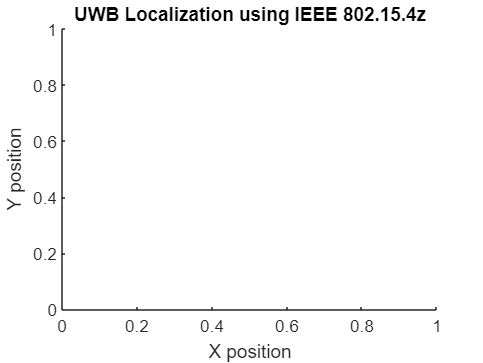

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocities for device and anchor nodes (change as needed)
deviceVelocity = [1, 5];   % Velocity of the device in x and y directions
nodeVelocities = [0.5, 1;    % Velocities of anchor nodes in x and y directions
                  -1, 0.5;
                  0.5, -1];

% Simulation parameters
numTimeSteps = 10;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;
nodeLoc = nodeLocInitial;

% Initialize figure for visualization
figure;
hold on;
xlabel('X position');
ylabel('Y position');
title('UWB Localization using IEEE 802.15.4z');


% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update anchor node positions
    nodeLoc = nodeLoc + nodeVelocities * timeStep;
    
    % Run the localization algorithm with updated positions
    % (code from the provided example)
    % For simplicity, I'll just print out the updated positions here
    disp(['Time Step: ' num2str(t)]);
    disp(['Device Location: ' num2str(deviceLoc)]);
    disp(['Anchor Node Locations:']);
    disp(nodeLoc);
    disp(' ');
    
    % Pause for visualization (optional)
    pause(0.1);
end

Time Step: 1


Device Location: 50.1         50.5


Anchor Node Locations:


   40.0500   41.1000
   61.9000   83.0500
   87.0500   23.9000



Time Step: 2


Device Location: 50.2           51


Anchor Node Locations:


   40.1000   41.2000
   61.8000   83.1000
   87.1000   23.8000



Time Step: 3


Device Location: 50.3         51.5


Anchor Node Locations:


   40.1500   41.3000
   61.7000   83.1500
   87.1500   23.7000



Time Step: 4


Device Location: 50.4           52


Anchor Node Locations:


   40.2000   41.4000
   61.6000   83.2000
   87.2000   23.6000



Time Step: 5


Device Location: 50.5         52.5


Anchor Node Locations:


   40.2500   41.5000
   61.5000   83.2500
   87.2500   23.5000



Time Step: 6


Device Location: 50.6           53


Anchor Node Locations:


   40.3000   41.6000
   61.4000   83.3000
   87.3000   23.4000



Time Step: 7


Device Location: 50.7         53.5


Anchor Node Locations:


   40.3500   41.7000
   61.3000   83.3500
   87.3500   23.3000



Time Step: 8


Device Location: 50.8           54


Anchor Node Locations:


   40.4000   41.8000
   61.2000   83.4000
   87.4000   23.2000



Time Step: 9


Device Location: 50.9         54.5


Anchor Node Locations:


   40.4500   41.9000
   61.1000   83.4500
   87.4500   23.1000



Time Step: 10


Device Location: 51           55


Anchor Node Locations:


   40.5000   42.0000
   61.0000   83.5000
   87.5000   23.0000




% After the simulation, you can perform any further analysis or visualization needed

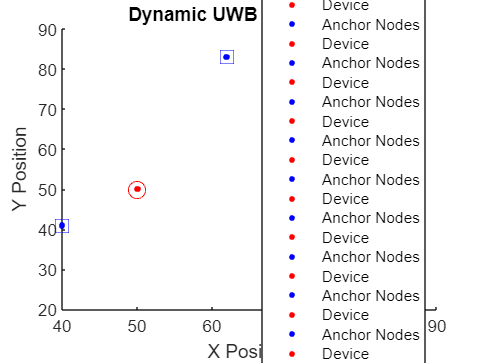

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocities for device and anchor nodes (change as needed)
deviceVelocity = [0.1, 0.05];   % Velocity of the device in x and y directions
nodeVelocities = [0.05, 0.1;    % Velocities of anchor nodes in x and y directions
                  -0.1, 0.05;
                  0.05, -0.1];

% Simulation parameters
numTimeSteps = 10;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;
nodeLoc = nodeLocInitial;

% Initialize plot variables
figure;
hold on;
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');

% Plot initial positions of device and anchor nodes
plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device Initial');
plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Main simulation loop
for t = 1:numTimeSteps
    % Update device position
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Update anchor node positions
    nodeLoc = nodeLoc + nodeVelocities * timeStep;
    
    % Plot updated positions
    plot(deviceLoc(1), deviceLoc(2), 'r.', 'MarkerSize', 10, 'DisplayName', 'Device');
    plot(nodeLoc(:, 1), nodeLoc(:, 2), 'b.', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');
    
    % Run the localization algorithm with updated positions
    % (code from the provided example)
    % ...
    
    % Pause for visualization (optional)
    pause(0.1);
end

% Add legend
legend('Location', 'best');